clear all
close all

addpath("Immagini\06_binning")

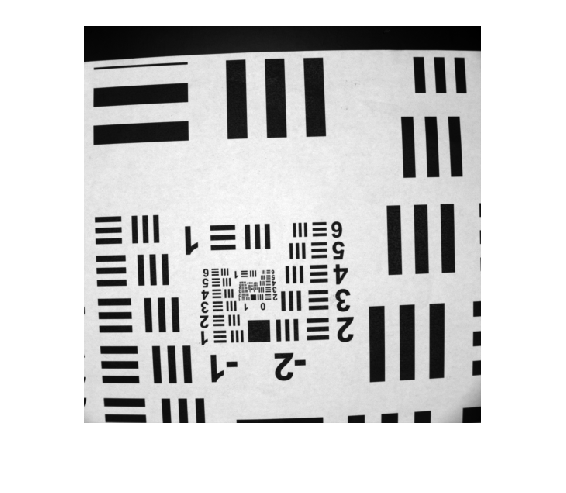

im_1 = importdata("Risoluzione_B2_t05_f4.asc");
im_1 = im_1(:,2:end);

noise_1 = importdata("Risoluzione_buio_B2_t05_f4.asc");
noise_1 = noise_1(:,2:end);

im_1 = im_1 - noise_1;

imshow(im_1,[])

x = [213  241];
y = [-408 -408];

pixel_dist = round(sqrt((x(1)-x(2))^2 + (y(1)-y(2))^2))

pixel_dist = 28

conv_factor = pixel_dist/10 % pixel/mm

conv_factor = 2.8000

close all hidden;

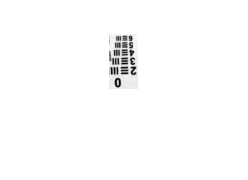

group_0 = im_1(314:368,223:251);
imshow(group_0, [])

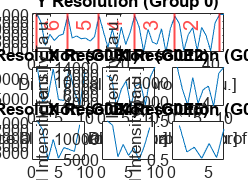


subplot(3,3,[1,2,3]);
y_res0 = improfile(group_0, [16 16], [1 43]);
plot(y_res0)
title("Y Resolution (Group 0)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along y profile [a.u.]")
xline(42, 'LineWidth', 1, 'Color', 'r')
xline(32, 'LineWidth', 1, 'Color', 'r', 'Label', '2')
xline(23, 'LineWidth', 1, 'Color', 'r', 'Label', '3')
xline(15, 'LineWidth', 1, 'Color', 'r', 'Label', '4')
xline(8, 'LineWidth', 1, 'Color', 'r', 'Label', '5')
xline(1, 'LineWidth', 1, 'Color', 'r', 'Label', '6')

subplot(3,3,4);
x_res01 = improfile(im_1, [214 223], [320 320]);
plot(x_res01)
title("X Resolution (G0E1)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,5);
x_res02 = improfile(group_0, [1 11], [37 37]);
plot(x_res02)
title("X Resolution (G0E2)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,6);
x_res03 = improfile(group_0, [3 12], [29 29]);
plot(x_res03)
title("X Resolution (G0E3)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,7);
x_res04 = improfile(group_0, [4 12], [19 19]);
plot(x_res04)
title("X Resolution (G0E4)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,8);
x_res05 = improfile(group_0, [5 13], [12 12]);
plot(x_res05)
title("X Resolution (G0E5)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,9);
x_res06 = improfile(group_0, [7 13], [5 5]);
plot(x_res06)
title("X Resolution (G0E6)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

group_y = 0;
element_y = 4;

r_y = 2^(group_y+(element_y-1)/6);
R_y = 1/r_y

R_y = 0.7071


group_x = 0;
element_x = 6;

r_x = 2^(group_x+(element_x-1)/6);
R_x = 1/r_x

R_x = 0.5612

half = @(x) round(x/2);